**1. Default  Values of Spectrogram**

% STFT -- Short-Time-Fourier-Tranformation
% spectrogram, matlab built-in function

close all,clc
N = 1024;
n = 0:1:N-1;

w0 = 2*pi/5;
x = sin(w0*n)+10*sin(2*w0*n);
subplot(2,1,1)
plot(x)

subplot(2,1,2)
S = spectrogram(x,10,5);
spectrogram(x, 'yaxis')


**2. Frequency Along x-Axis**

t = 0:0.001:2;
% swept-frequency consine
% 扫频余弦
% frequency is variable depending on time.
x = chirp(t, 100,1,200,'quadratic');
% line, li
% quadratic, q
% logarithmic, lo


    Then, it will be oblivious on time-frequency axes.


figure;
subplot(2,1,1)
plot(t,x)

subplot(2,1,2)
% Hamming window
% 128, the length of very window
% 120, the length of overlap window
% 128, cyclinical frequencies specified in 128Hz
% 1e3, the sampling frequency, 1KHz
spectrogram(x, 128,120,2000,1e3)


**Blackman window**

figure;
subplot(2,1,1)
plot(blackman(128))

subplot(2,1,2)
spectrogram(x, blackman(128), 60, 128, 1e3)


**Power Spectral Denstities of Chirps**

t = 0:.001:2;
x = chirp(t, 100,1,200, 'q');
figure
spectrogram(x, 128, 120,128,1e3, 'yaxis');

**Spectrogram and Instantaneous Frequency**

Fs = 1000;
t = 0:1/Fs:2-1/Fs;
y = chirp(t, 100,1,200,'line');
figure;
spectrogram(y, 100, 80, 100, Fs, 'yaxis')
view(-77,72)
shading interp
colorbar off
figure;
[s, f, t, p] = spectrogram(y, 100, 80, 100, Fs);
[q, nd] = max(10*log10(p));
hold on;
plot3(t, f(nd), q, 'r', 'linewidth', 4)
colorbar
view(2)

Kaiser window

figure;
plot(kaiser(128,18))

** Spectrogram with Threshold**

Fs = 1000;
t = 0:1/Fs:2;
y= chirp(t, 100, 1, 200,'quadratic');
% set to zero those elements of the PSD smaller than -30dB
% Threshold, could be used as de-noising.
[~,~,~, pxx, fc, tc] = spectrogram(y, kaiser(128,18), 120, 128, Fs, ...
                                    'MinThreshold', -30);
 plot(tc(pxx>0), fc(pxx>0), '.')

**Track Chirps in Audio Signal**

 load splat;
 % to hear it.
 %  soundsc(y, Fs)
 sg = 400; % length of section
 ov = 300; % length of overlap
 % s, each column of s contains an estimate of the STFT frequency content of x.
 % f, cyclical frequencies
 % t, a vector of time instants
 % ps, power spectrum of each section.
 spectrogram(y, sg, ov, [], Fs, 'yaxis', 'MinThreshold', -100)
 [s, f, t, p] = spectrogram(y, sg, ov, [], Fs, 'yaxis')

s =    9.3131 + 0.0000i  10.6873 + 0.0000i  10.2583 + 0.0000i   8.8466 + 0.0000i   7.0245 + 0.0000i   5.9572 + 0.0000i   5.6859 + 0.0000i   5.4792 + 0.0000i   5.0605 + 0.0000i   4.5105 + 0.0000i   4.0125 + 0.0000i   3.5754 + 0.0000i   3.1951 + 0.0000i   2.8346 + 0.0000i   2.4677 + 0.0000i   2.2208 + 0.0000i   1.9903 + 0.0000i   1.7479 + 0.0000i   1.5938 + 0.0000i   1.4366 + 0.0000i   1.2375 + 0.0000i   1.0704 + 0.0000i   0.9400 + 0.0000i   0.8291 + 0.0000i   0.7519 + 0.0000i   0.6933 + 0.0000i   0.6332 + 0.0000i   0.5578 + 0.0000i   0.4944 + 0.0000i   0.4362 + 0.0000i   0.3980 + 0.0000i   0.3714 + 0.0000i   0.3390 + 0.0000i   0.3060 + 0.0000i   0.2692 + 0.0000i   0.2435 + 0.0000i   0.2271 + 0.0000i   0.2055 + 0.0000i   0.1870 + 0.0000i   0.1668 + 0.0000i   0.1457 + 0.0000i   0.1363 + 0.0000i   0.1316 + 0.0000i   0.1220 + 0.0000i   0.1088 + 0.0000i   0.0940 + 0.0000i   0.0839 + 0.0000i   0.0840 + 0.0000i   0.0855 + 0.0000i   0.0808 + 0.0000i   0.0709 + 0.0000i   0.0607 + 0.0000i   0.056

f =      0
    16
    32
    48
    64
    80
    96
   112
   128
   144


t =     0.0244    0.0366    0.0488    0.0610    0.0732    0.0854    0.0977    0.1099    0.1221    0.1343    0.1465    0.1587    0.1709    0.1831    0.1953    0.2075    0.2197    0.2319    0.2441    0.2563    0.2686    0.2808    0.2930    0.3052    0.3174    0.3296    0.3418    0.3540    0.3662    0.3784    0.3906    0.4028    0.4150    0.4272    0.4395    0.4517    0.4639    0.4761    0.4883    0.5005    0.5127    0.5249    0.5371    0.5493    0.5615    0.5737    0.5859    0.5981    0.6104    0.6226


p =    1.0e-04 *

    0.6677    0.8793    0.8101    0.6025    0.3799    0.2732    0.2489    0.2311    0.1971    0.1566    0.1239    0.0984    0.0786    0.0619    0.0469    0.0380    0.0305    0.0235    0.0196    0.0159    0.0118    0.0088    0.0068    0.0053    0.0044    0.0037    0.0031    0.0024    0.0019    0.0015    0.0012    0.0011    0.0009    0.0007    0.0006    0.0005    0.0004    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6284    0.6954    0.6151    0.4739    0.2669    0.1856    0.1837    0.1737    0.1485    0.1131    0.0913    0.0731    0.0563    0.0441    0.0347    0.0279    0.0224    0.0173    0.0146    0.0121    0.0091    0.0061    0.0049    0.0038    0.0031    0.0027    0.0022    0.0019    0.0013    0.0011    0.0009    0.0008    0.0007    0.0005    0.0004    0.0003    0.0003    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000 

 colormap bone
 f1 = f>100;
 t1 = t< 0/75;
 m1 = medfreq(p(f1,t1), f(f1))

m1 = 1x0 double

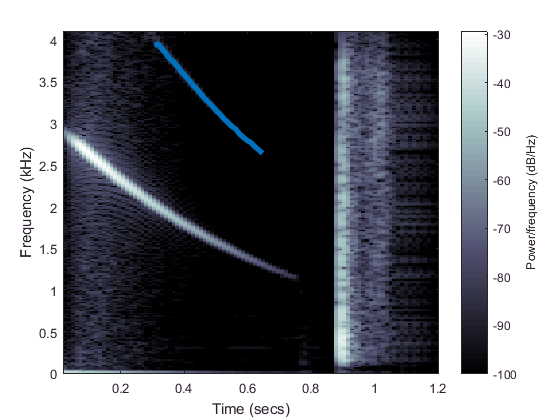

 f2 = f >2500;
 t2 = t>0.3 &t<0.65;
 m2 = medfreq(p(f2, t2), f(f2));
 hold on ;
 plot(t(t1), m1/1000, 'r','linewidth', 4)
 hold on;
 plot(t(t2), m2/1000, 'linewidth', 4)
 hold off